# Frequency Analysis of the Cardiac-Related Signal

This script studies the persistent harmonics of the CRS signal obtained under apnea.

% Load example datafile of healthy subject
filenameCRS = "C:\Users\silva.LSMEDIT\Documents\sciebo\ProjektSeminar\dataset\subject1\stage1\imgB1.mat";
load(filenameCRS);

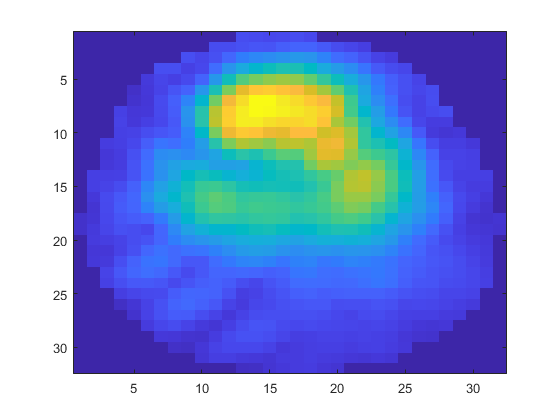

% Create example signal to analyse
figure; imagesc(max(imgB1,[],3));

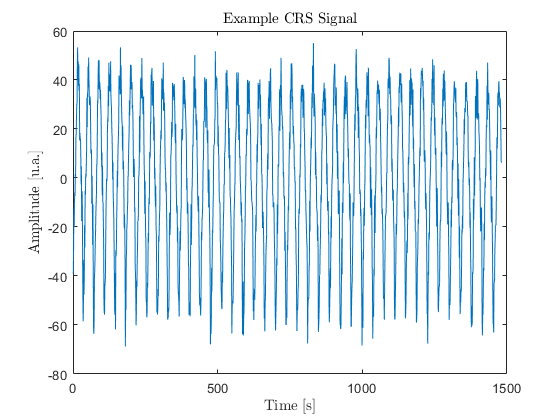

refPix = [15, 21];
signalCRS = squeeze(imgB1(refPix(1),refPix(2),:));
figure; plot(signalCRS); title('Example CRS Signal', 'Interpreter', 'Latex'); ylabel('Amplitude [u.a.]', 'Interpreter', 'Latex'); xlabel('Time [s]', 'Interpreter', 'Latex');

First, the spectogram of the signal is taken, to make sure the frequency peaks are constant over the recording and are not a consequence of different heart-rates. Further analysis was performed on the 7 frequency components which seem to persist in time: ~1.35 Hz, ~2.6 Hz, ~4 Hz, ~5.3 Hz, ~6.6 Hz, ~9.5 Hz, ~21.5 Hz.

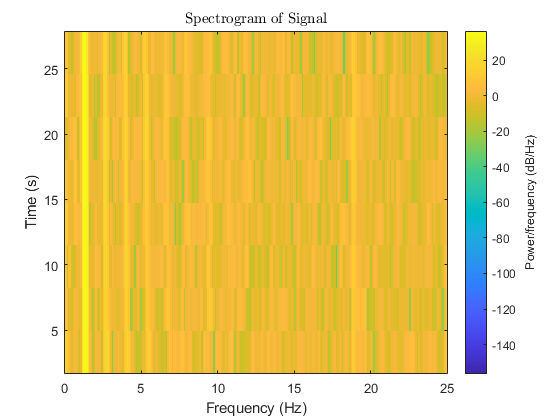

spectrogram(signalCRS,[],[],[],50)
title('Spectrogram of Signal', 'Interpreter', 'Latex');

The seven components were isolated as best as possible with high-order IIR filtering.

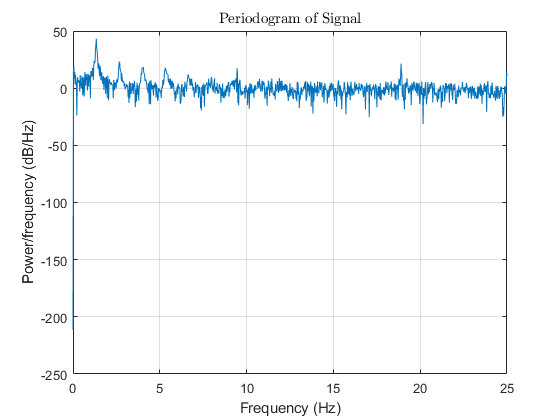

figure; periodogram(signalCRS,[],[],50); title('Periodogram of Signal', 'Interpreter', 'Latex');

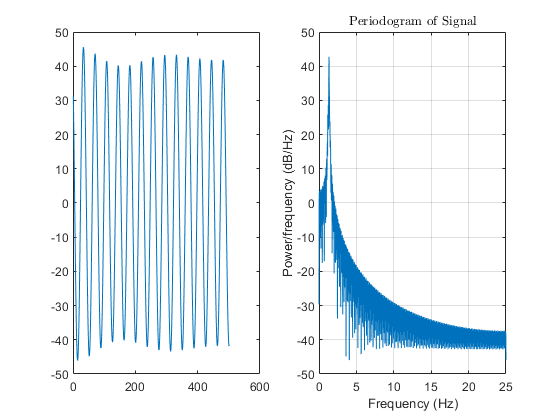


% Matrix with 7 signal bands
b = zeros(length(signalCRS), 7);
window = [500:1000];

% 1st band (~1.35 Hz)
d = band1;
b(:,1) = filtfilt(d.sosMatrix,d.ScaleValues,signalCRS);

figure; 
subplot(1,2,1);plot(b(window,1));
subplot(1,2,2); periodogram(b(:,1),[],[],50)
title('Periodogram of Signal', 'Interpreter', 'Latex');

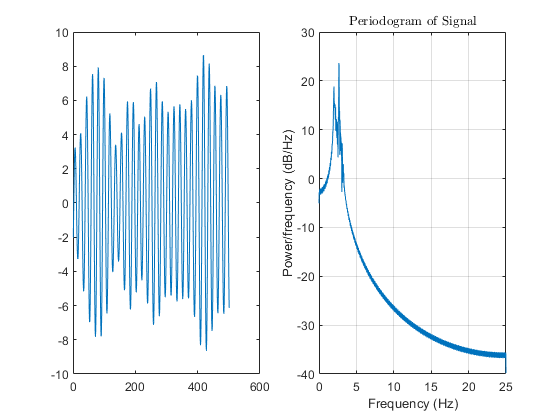


% 2nd band (~2.6 Hz)
d = band2;
b(:,2) = filtfilt(d.sosMatrix,d.ScaleValues,signalCRS);

figure; 
subplot(1,2,1);plot(b(window,2));
subplot(1,2,2); periodogram(b(:,2),[],[],50)
title('Periodogram of Signal', 'Interpreter', 'Latex');

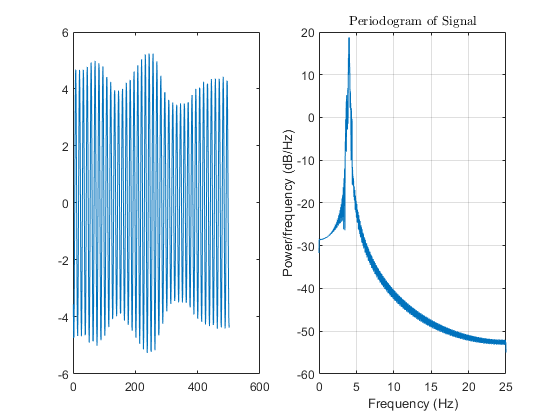


% 3rd band (~4 Hz)
d = band3;
b(:,3) = filtfilt(d.sosMatrix,d.ScaleValues,signalCRS);

figure; 
subplot(1,2,1);plot(b(window,3));
subplot(1,2,2); periodogram(b(:,3),[],[],50)
title('Periodogram of Signal', 'Interpreter', 'Latex');

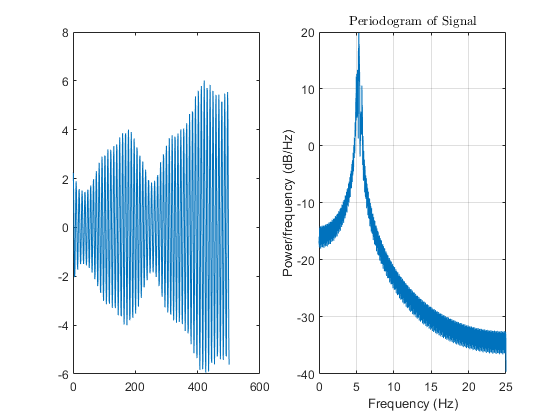


% 4th band (~5.3 Hz)
d = band4;
b(:,4) = filtfilt(d.sosMatrix,d.ScaleValues,signalCRS);

figure; 
subplot(1,2,1);plot(b(window,4));
subplot(1,2,2); periodogram(b(:,4),[],[],50)
title('Periodogram of Signal', 'Interpreter', 'Latex');

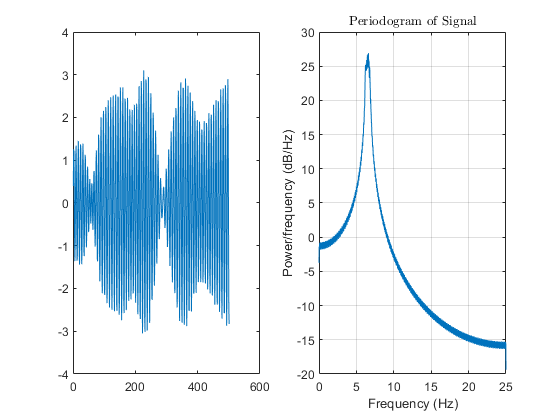


% 5th band (~6.6 Hz)
d = band5;
b(:,5) = filtfilt(d.sosMatrix,d.ScaleValues,signalCRS);

figure; 
subplot(1,2,1);plot(b(window,5));
subplot(1,2,2); periodogram(b(:,5),[],[],50)
title('Periodogram of Signal', 'Interpreter', 'Latex');

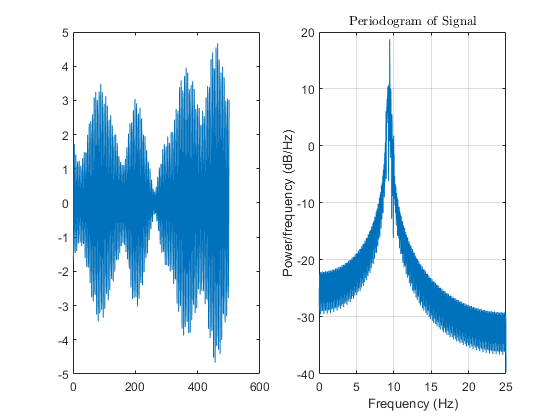


% 6th band (~9.5 Hz)
d = band6;
b(:,6) = filtfilt(d.sosMatrix,d.ScaleValues,signalCRS);

figure; 
subplot(1,2,1);plot(b(window,6));
subplot(1,2,2); periodogram(b(:,6),[],[],50)
title('Periodogram of Signal', 'Interpreter', 'Latex');

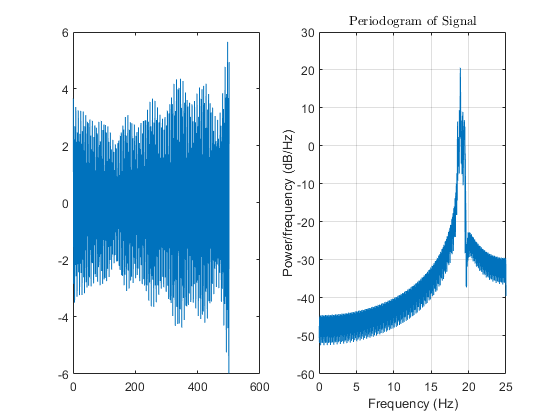


% 7th band (~21.5 Hz)
d = band7;
b(:,7) = filtfilt(d.sosMatrix,d.ScaleValues,signalCRS);

figure; 
subplot(1,2,1);plot(b(window,7));
subplot(1,2,2); periodogram(b(:,7),[],[],50)
title('Periodogram of Signal', 'Interpreter', 'Latex');

Below is the reconstruction of the signal by summation of the isolated parts (the user can choose the range of components to sum). It seems that the first component is largely dominant, but, when removed, the conjugation of the remaining ones with the exception of the last display an interesting waveform. This waveform is similar to that of ECG (notice how the shaded error plot forms a very distinct waveform), and this correspondance should be further looked into. The question remains whether these components represent different contributions from pulsatility and perfusion. The inclusion of the last component seems to include only noise.

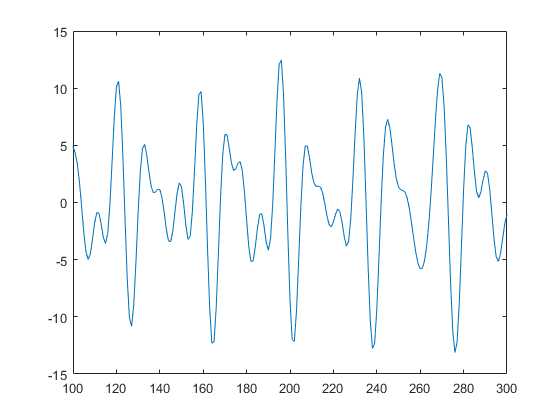

firstComp = 2; lastComp = 4;
recon = sum(b(window,[firstComp:lastComp]),2);
figure; plot(recon); xlim([100,300]);

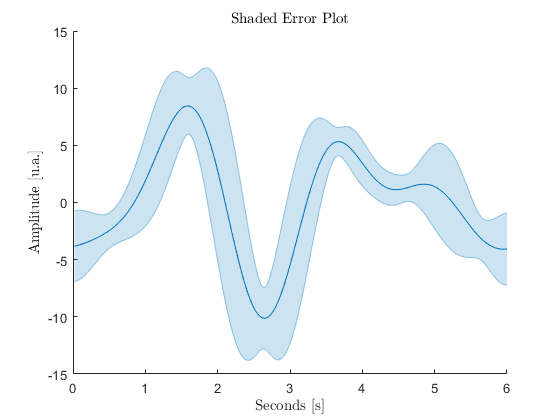

avgBeat = avgCycle(recon,50,300,0);

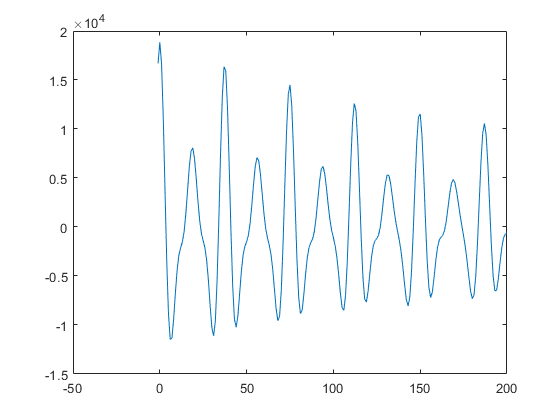

% Calculate least correlation delay
maxLag = 200;
[r,lags] = xcorr(recon,recon,maxLag); r = r(200:end); lags = lags(200:end);
figure; plot(lags,r);

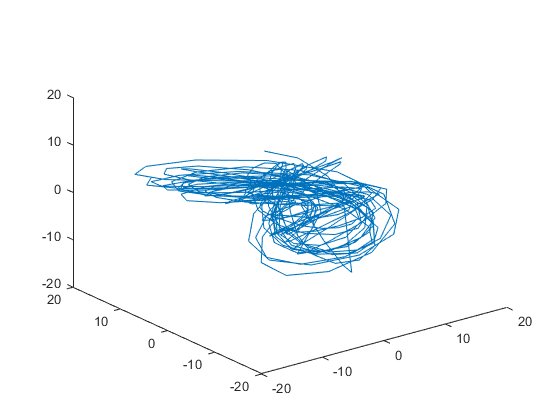

delay = 4;
signalSeg = recon;
x1 = signalSeg;
x2 = circshift(signalSeg,delay);
x3 = circshift(signalSeg,2 * delay);

figure; plot3(x1,x2,x3)

Finally, a graph showing the cumulative effect of successively adding components is plotted.

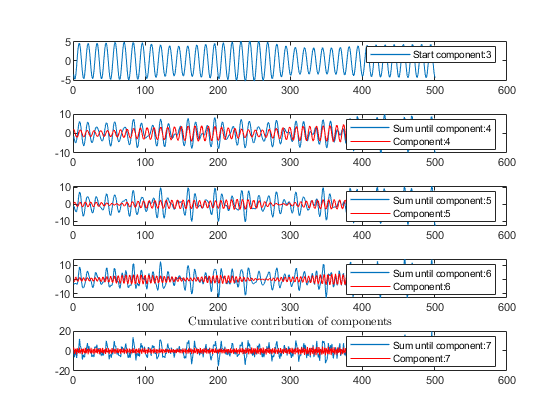

startComp = 3;
totalPlots = 7 - startComp + 1;

figure;
subplot(totalPlots,1,1);
plot(sum(b(window,startComp),2), 'LineWidth', 1);
legend({strcat('Start component: ',num2str(startComp))})

count = 2;
for band = startComp + 1:7
    subplot(totalPlots,1,count);
    plot(sum(b(window,startComp:band),2), 'LineWidth', 1); hold on;
    plot(b(window,band),'LineWidth', 0.5, 'Color', 'r');
    legend({strcat('Sum until component: ',num2str(band)), strcat('Component: ',num2str(band))})
    
    count = count + 1;
end

title('Cumulative contribution of components', 'Interpreter', 'Latex');